# Signal Quality Indicators for breathing signal

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

Dependencies: files PEX_T1.mat, Free_T1.mat and Irregular_T1.mat. Code: br_rate_est.m

### Acknowledgements

This notebook uses data from the database described in the paper: Shafiq, G., Veluvolu, K. Multimodal chest surface motion data for respiratory and cardiovascular monitoring applications. *Sci Data* **4, **170052 (2017). [https://doi.org/10.1038/sdata.2017.52](https://doi.org/10.1038/sdata.2017.52)

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter9/Signal Quality'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Introduction

In this notebook, we are going to load respiratory belt and temperature sensor data and to show the waveforms as well as to compute several signal quality indicators.

## Loading breathing data 

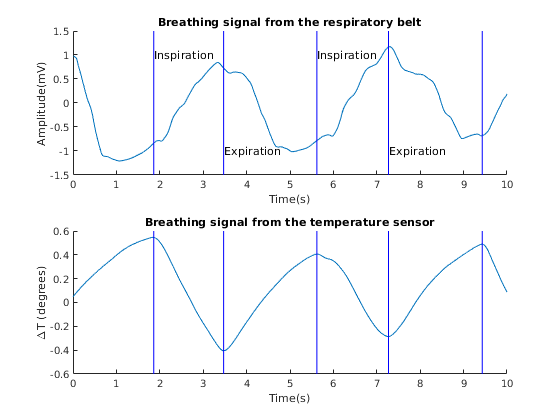

% Loading breathing data obtained after exercize
load('PEX_T1.mat')
figure
fs=100;
lim=105*fs:115*fs;
t=1/fs:1/fs:length(mp36_s(1,:))/fs;
[m,i_max]=findpeaks(mp36_s(4,lim));
[m,i_min]=findpeaks(-mp36_s(4,lim));
i_all=[i_min,i_max];
%plot(t/60,mp36_s(1,:))
subplot(211)
hold on
plot(t(lim)-t(lim(1)),smooth(mp36_s(2,lim),25))
for i=1:length(i_all)
    plot([i_all(i)/fs, i_all(i)/fs],ylim.*ones(1,2),'b')
end
hold off
text(i_min/fs,-1*ones(1,length(i_min)),'Expiration')
text(i_max(1:end-1)/fs,ones(1,length(i_max(1:end-1))),'Inspiration')

xlabel('Time(s)')
ylabel('Amplitude(mV)')
title('Breathing signal from the respiratory belt')
subplot(212)
hold on
plot(t(lim)-t(lim(1)),mp36_s(4,lim))
xlabel('Time(s)')
ylabel('\DeltaT (degrees)')
title('Breathing signal from the temperature sensor')
for i=1:length(i_all)
    plot([i_all(i)/fs, i_all(i)/fs],ylim.*ones(1,2),'b')
end
hold off
exportgraphics(gcf,"Fig9.3.jpg", 'Resolution',600)

%text(i_min/fs,ylim*ones(1,length(i_min)),'expiration')
%text(i_max/fs,-ylim*ones(1,length(i_max)),'inspiration')


## SQI 

### Loading signal after exercise

load('PEX_T1.mat')
%load('Free_T1.mat')
t=1/fs:1/fs:length(mp36_s(1,:))/fs;

resp=mp36_s(4,:);
% Define frequency ranges of interest fot the signal
Fmask_low_sig=br_rate_est(resp',fs)/60-0.1;
Fmask_high_sig=br_rate_est(resp',fs)/60+0.1;
Fmask_low_all=0.05;
Fmask_high_all=1;

% Compute periodogram
NyquistF = fs/2;
FResBPM = 0.5;
Nfft = (60*2*NyquistF)/FResBPM; %number of bins in power spectrum
[Pxx,F] = periodogram(resp,hamming(length(resp)),Nfft,fs);

% Compute power in the frequency band of the signal of interest
FMask1 = (F >= Fmask_low_sig)&(F <= Fmask_high_sig);
PowerSig = sum(Pxx(FMask1));

% Compute power in the total frequency band 
FMask2 = (F >= Fmask_low_all)&(F <= Fmask_high_all);
PowerAll = sum(Pxx(FMask2));

% Compute signal quality indices = ratio of the power in the 
PowerRatio=PowerSig/PowerAll;
if PowerRatio < 0.9 && PowerRatio > 0.5
    pSQI=1
else
    pSQI=0
end

pSQI = 1

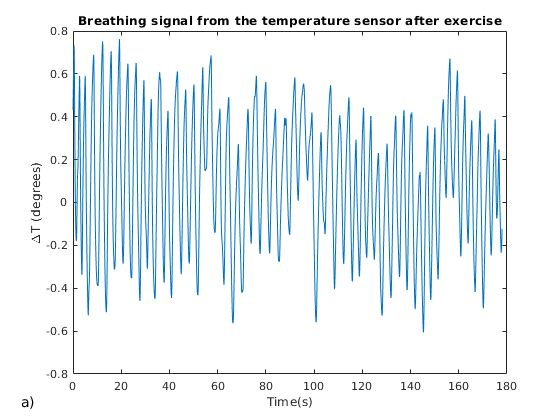

figure
% subplot(211)
% plot(t,mp36_s(2,:))
% xlabel('Time(s)')
% ylabel('Amplitude(mV)')
% title('Signal from respiratory belt')

plot(t,mp36_s(4,:))
xlabel('Time(s)')
ylabel('\DeltaT (degrees)')
title('Breathing signal from the temperature sensor after exercise')
annonation_save('a)',"Fig9.4a.jpg", SAVE_FLAG);

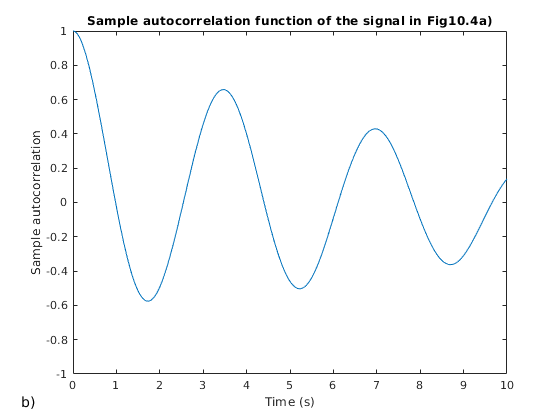

figure
[normalizedACF, lags] = autocorr(resp, 'NumLags',1000,'NumSTD',2);
plot(lags/fs,normalizedACF)
xlabel('Time (s)')
ylabel('Sample autocorrelation')
title('Sample autocorrelation function of the signal in Fig9.4a)')
ylim([-1,1])
annonation_save('b)',"Fig9.4b.jpg", SAVE_FLAG);

### Loading irregular breathing signal

load('Irregular_T1.mat')
t=1/fs:1/fs:length(mp36_s(1,:))/fs;


resp=mp36_s(4,:);
% Define frequency ranges of interest fot the signal
Fmask_low_sig=br_rate_est(resp',fs)/60-0.1;
Fmask_high_sig=br_rate_est(resp',fs)/60+0.1;
Fmask_low_all=0.05;
Fmask_high_all=1;

% Compute periodogram
NyquistF = fs/2;
FResBPM = 0.5;
Nfft = (60*2*NyquistF)/FResBPM; %number of bins in power spectrum
[Pxx,F] = periodogram(resp,hamming(length(resp)),Nfft,fs);

% Compute power in the frequency band of the signal of interest
FMask1 = (F >= Fmask_low_sig)&(F <= Fmask_high_sig);
PowerSig = sum(Pxx(FMask1));

% Compute power in the total frequency band 
FMask2 = (F >= Fmask_low_all)&(F <= Fmask_high_all);
PowerAll = sum(Pxx(FMask2));

% Compute signal quality indices = ratio of the power in the 
PowerRatio=PowerSig/PowerAll;
if PowerRatio < 0.9 && PowerRatio > 0.5
    pSQI=1
else
    pSQI=0
end

pSQI = 0

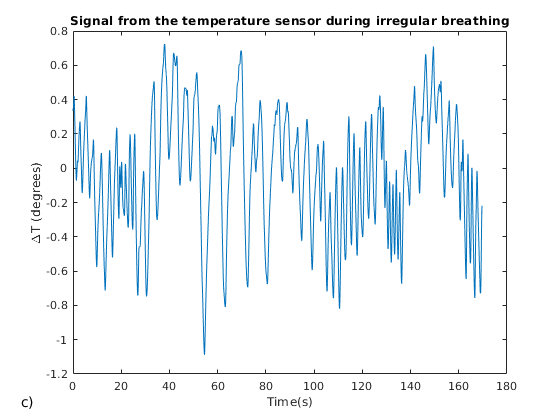

figure
% subplot(211)
% plot(t,mp36_s(2,:))
% xlabel('Time(s)')
% ylabel('Amplitude(mV)')
% title('Signal from respiratory belt')

plot(t,mp36_s(4,:))
xlabel('Time(s)')
ylabel('\DeltaT (degrees)')
title('Signal from the temperature sensor during irregular breathing')
annonation_save('c)',"Fig9.4c.jpg", SAVE_FLAG);

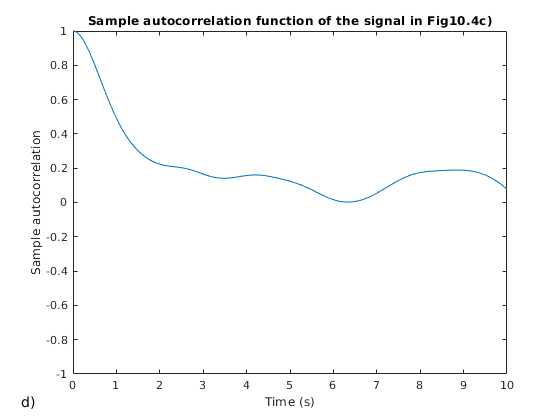

figure
[normalizedACF, lags] = autocorr(resp, 'NumLags',1000,'NumSTD',2);
plot(lags/fs,normalizedACF)
xlabel('Time (s)')
ylabel('Sample autocorrelation')
title('Sample autocorrelation function of the signal in Fig9.4c)')
ylim([-1,1])
annonation_save('d)',"Fig9.4d.jpg", SAVE_FLAG);

## Exersizes

Excersize 1: Show ACF for cases when respiratory belt waveform is selected instead of thermal sensor waveform.

Excersize 2: Instead of loading waveform obtained after exercise from the file 'PEX_T1.mat', load the waveform 'Free_T1.mat' that corresponds to the free breathing signal. Compute PowerRatio and show ACF. Why is the quality lower than in the case of the waveform after exercise?

Excersize 3: How does the length of the signal affects the  PowerRatio and ACF. Reduce signals to 60 sec.